% (y/(x^2+y^2)-y)*dx+(exp(y)-x-x/(x^2+y^2))*dy

clear
% 1)
% y'=-(y/(x^2+y^2)-y)/(exp(y)-x-x/(x^2+y^2))
% syms x y(x)
% eqn=diff(y(x))==-(y/(x^2+y^2)-y)/(exp(y)-x-x/(x^2+y^2))
% ySol=dsolve(eqn)
% [ empty sym ]

% 2)
syms x y dx dy 
eq1=(y/(x^2+y^2)-y)*dx+(exp(y)-x-x/(x^2+y^2))*dy

$$eq1 = -\mathrm{dy}\,\left(x-{\mathrm{e}}^{y}+\frac{x}{x^{2}+y^{2}}\right)-\mathrm{dx}\,\left(y-\frac{y}{x^{2}+y^{2}}\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} \frac{y}{x^{2}+y^{2}}-y & {\mathrm{e}}^{y}-x-\frac{x}{x^{2}+y^{2}} \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = \frac{y}{x^{2}+y^{2}}-y$$

$$Q = {\mathrm{e}}^{y}-x-\frac{x}{x^{2}+y^{2}}$$

f=simplify(diff(Q,x)-diff(P,y))

$$f = 0$$

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = \mathrm{atan}\left(\frac{x}{y}\right)+C\left(y\right)-x\,y$$

% atan(x/y) + C(y) - x*y
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)-x-\frac{x}{y^{2}\,\left(\frac{x^{2}}{y^{2}}+1\right)}$$

% diff(C(y), y) - x - x/(y^2*(x^2/y^2 + 1))
dCy=simplify(dUy-Q)

$$dCy = \frac{\partial }{\partial y}C\left(y\right)-{\mathrm{e}}^{y}$$

% diff(C(y), y) - exp(y)
C(y)=int(exp(y),y)

$$C(y) = {\mathrm{e}}^{y}$$

% exp(y)
% atan(x/y) + exp(y) - x*y = C1

% 3)
x0=0;y0=1;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = \mathrm{atan}\left(\frac{x}{y}\right)-\mathrm{e}+{\mathrm{e}}^{y}-x\,y$$

syms C
eq2=U==C

$$eq2 = \mathrm{atan}\left(\frac{x}{y}\right)-\mathrm{e}+{\mathrm{e}}^{y}-x\,y=C$$

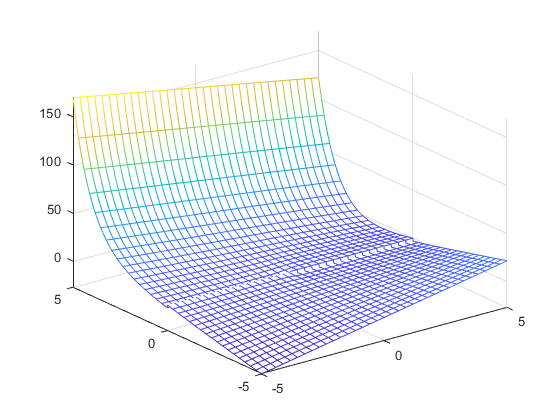

fmesh(U)